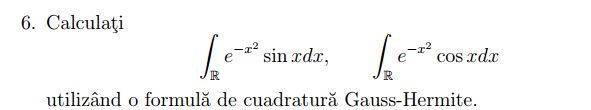

f1 = @(x) sin(x);
f2 = @(x) cos(x);

% These integrals have known exact values:
% I1 = 0 (odd function over symmetric interval)
% I2 = sqrt(pi)

I1_exact = 0;
I2_exact = sqrt(pi);
eps = 1e-8;

n = 2;
max_n = 50;
found1 = false;
found2 = false;

while ~(found1 && found2) && n <= max_n
    [nodes, weights] = gauss_hermite(n);
    
    I1 = sum(weights .* f1(nodes));
    I2 = sum(weights .* f2(nodes));
    
    err1 = abs(I1 - I1_exact);
    err2 = abs(I2 - I2_exact);
    
    if ~found1 && err1 < eps
        n1 = n;
        found1 = true;
        fprintf('I1 accurate with n = %d, error = %.2e\n', n1, err1);
    end
    
    if ~found2 && err2 < eps
        n2 = n;
        found2 = true;
        fprintf('I2 accurate with n = %d, error = %.2e\n', n2, err2);
    end
    
    n = n + 1;
end

I1 accurate with n = 2, error = 0.00e+00



fprintf('\nResults:\n');


Results:


fprintf('sin(x): approx = %.10f, error = %.2e, n = %d\n', I1, err1, n1);

sin(x): approx = -0.0000000000, error = 1.28e-16, n = 2


fprintf('cos(x): approx = %.10f, error = %.2e, n = %d\n', I2, err2, n2);

cos(x): approx = 1.3803884470, error = 3.92e-01, n = 13
